# Tutorial: Running an Image Scan

This software is made available under the MIT license. See SONIC/LICENSE for details.

In this example, we will be using `SONIC` to analyze the edge on the Asteroid Bennu. We will first process the image by removing smear, which will make the edge clearer. Then, we will use `SONIC` to create scan lines along the direction of illumination. By sampling the image intensity along these scan lines we can analyze the curve created by the increase in intensity over the asteroid's horizon. Analyzing a horizon edge can be very useful in OPNAV. For example, in horizon based OPNAV.

### Process the Image: Remove Smear

First, we read in the image we are going to be analyzing, and store it in a SONIC image object. This will allow us to manipulate and use the image using SONIC's tools. You'll notice that this image of Bennu has significant smear in the image above and below the asteroid body. This is caused by exposure occurring while the CCD sensor is reading in pixels (before the image is taken) and reading out pixels (after the image is taken). This effect could greatly impact edge analysis, so we want to remove it first. To do this, we use the `Image` class method `removeSmearCCD`, which will remove the smear in the image based on the image exposure time and read in and out time. For this image, the read in and out time is the same (and therefore is input as a scalar), but if the read in time and read out time differ, they can be input together as a 1 by 2 vector. For more information on the `removeSmearCCD` method, run `help sonic.Image.removeSmearCCD`. The original image and the cleaned image are shown side by side below for comparison.

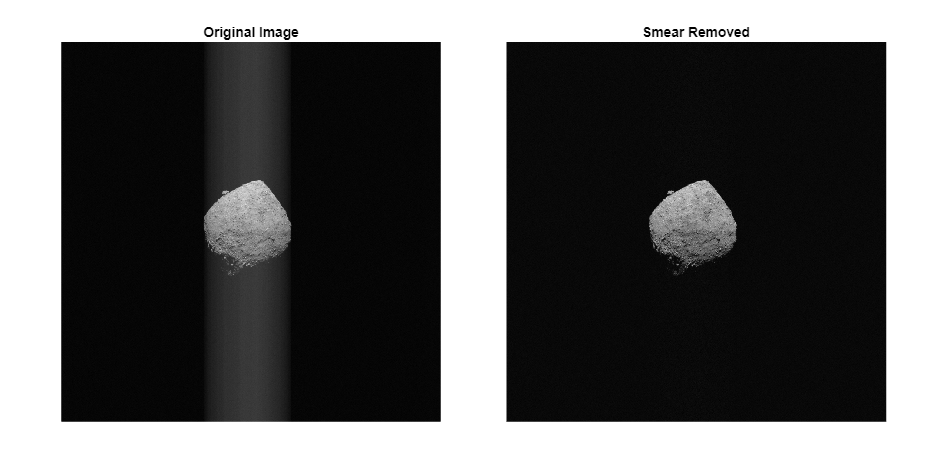

image_fn = "+examples/+data/20181201T100711S900_map_L0pan.fits"; 
im_raw = flipud(fitsread(image_fn));
im_raw_obj = sonic.Image(im_raw);

t_exp = 0.45/1000; % ms to s conversion
t_inout = 1*10^-6; % micros to s conversion
im_clean_obj = im_raw_obj.removeSmearCCD(t_exp,t_inout);

fig1 = figure;
fig1.Position(3:4) = [1000, 500];
t = tiledlayout(1,2);
nexttile
imshow(im_raw,[])
title('Original Image')
nexttile
imshow(im_clean_obj.DNmat,[])
title('Smear Removed')
t.TileSpacing = 'compact';
t.Padding = 'compact';

### Create Scan Lines

Now that the image is cleaned, we can proceed with our horizon analysis. In this case, we want to scan the image with a set of parallel scan lines in the same direction of illumination. The `SONIC` class `ScanLines` is particularly useful for this application, because it stores both lines and their directionality. Lines defined to have positive directionality are read in the direction of increasing u, or in the case of verticle lines, from top to bottom. This class allows for any number of scan lines to be created and stored in the objects, each with their own direction and equation. For more information, you can run `help sonic.Scanlines`. For the purposes of creating parallel scan lines, we will use the `Scanlines` method `getParallelLines`, which can generate evenly spaced (by drho), parallel scan lines in the image based on the direction of illumination. 

Once we have the scan lines, we can call the `Image` method `getLine` to sample the image intensity along these scan lines. The `getLine` method uses bilinear interpolation to estimate the digital number at each location, so the intensity values lie exactly on the scan line, at intervals of one pixel along the lines. To visualize, we can plot these lines in the image to see that they align with the direction of illumination. Additionally, we can select one of the lines passing through Bennu (the bolded red line), and analyze the pixel intensities over the change from background noise to Bennu. As expected, we observe a large jump in intensity at the horizon location.

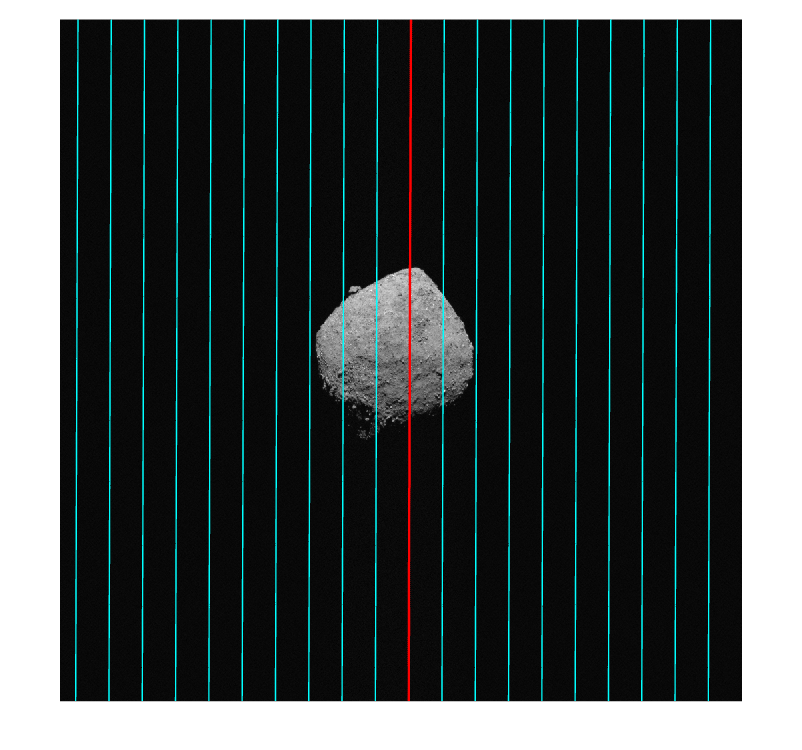

u_illum = [-0.003373735745344; 0.999994308937366];
drho = 50;
scan_lines = sonic.ScanLines.getParallelLines(im_clean_obj, drho, u_illum);
[scan_values, scan_locs, line_lengths] = im_clean_obj.getLine(scan_lines);

figure;
imshow(im_clean_obj.DNmat,[])
hold on
for i = 1:length(scan_locs)
    plot_pts = scan_locs{i};
    if i == 11
        plot(plot_pts.r2(1,:), plot_pts.r2(2,:),'r','LineWidth',2)
    elseif ~isempty(plot_pts)
        plot(plot_pts.r2(1,:), plot_pts.r2(2,:),'c')
    end

end
hold off

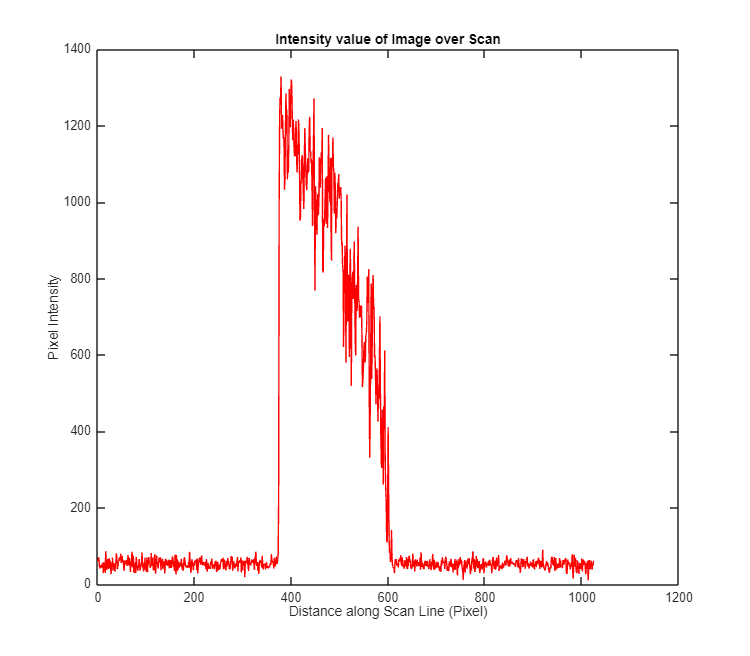

fig2 = figure;
fig2.Position(3:4) = [800, 700];
plot(1:line_lengths(11),scan_values{11},'r')
ylabel('Pixel Intensity')
xlabel('Distance along Scan Line (Pixel)')
title('Intensity value of Image over Scan')

As previously mentioned, the `Scanlines` class allows for a more generic use of scan lines. We may define any number of unique scan lines and obtain the image values by using the basic constructor. For example, we can take lines intersecting Bennu as some arbitrary angle. To set up custom scan lines, we must first create our `Lines2` object, which will contain the representations of our lines. There are multiple ways to construct a `Lines2` object (run `help` `sonic.Lines2` for more information), but here we are going to take advantag of the rho theta line representation, which is a quick and intuitive way to define a line in the image. Here we define 4 arbitrary scan lines to demonstrate the flexibility. 

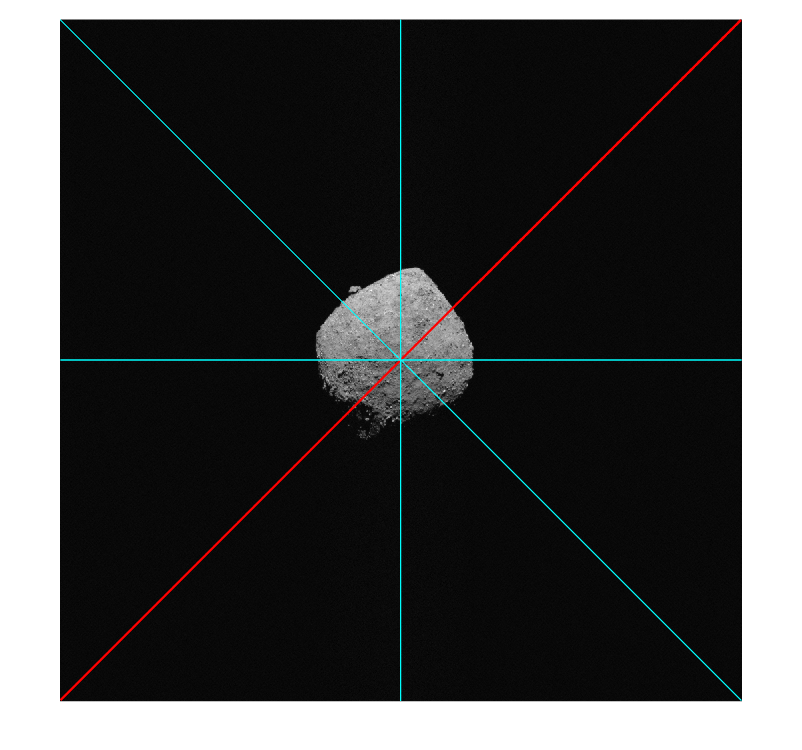

thetas = [45*pi/180 -45*pi/180 0 pi/2];
rhos = [sqrt(im_clean_obj.rows^2 + im_clean_obj.rows^2)/2 0 im_clean_obj.cols/2 im_clean_obj.rows/2];
lines = sonic.Lines2(thetas,rhos);
ispos = [0; 1; 1; 1];
scan_lines_cross = sonic.ScanLines(lines, ispos);
[scan_values_cross, scan_locs_cross, line_lengths_cross] = im_clean_obj.getLine(scan_lines_cross);

figure;
imshow(im_clean_obj.DNmat,[])
hold on
for i = 1:length(scan_locs_cross)
    plot_pts = scan_locs_cross{i};
    if i == 1
        plot(plot_pts.r2(1,:), plot_pts.r2(2,:),'r','LineWidth',2)
    elseif ~isempty(plot_pts)
        plot(plot_pts.r2(1,:), plot_pts.r2(2,:),'c')
    end
end
hold off

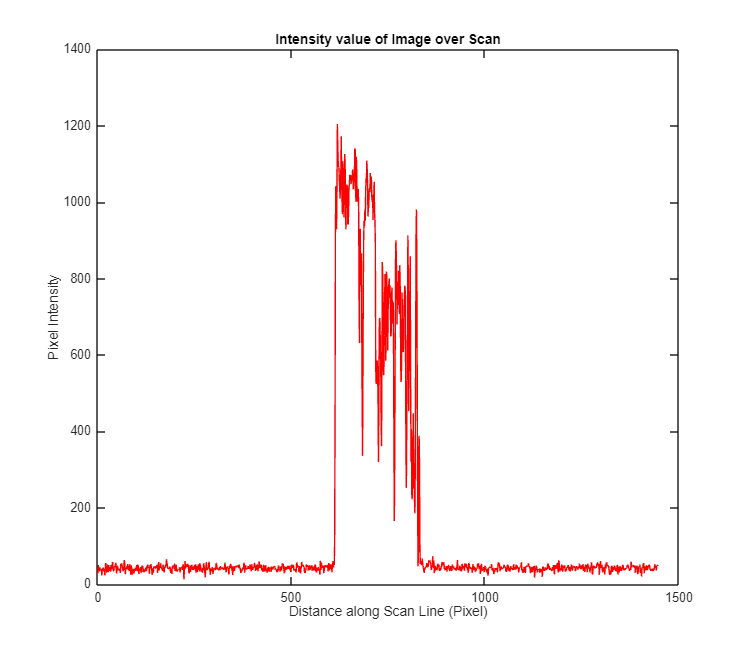

fig4 = figure;
fig4.Position(3:4) = [800, 700];
plot(1:line_lengths_cross(1),scan_values_cross{1},'r')
ylabel('Pixel Intensity')
xlabel('Distance along Scan Line (Pixel)')
title('Intensity value of Image over Scan')